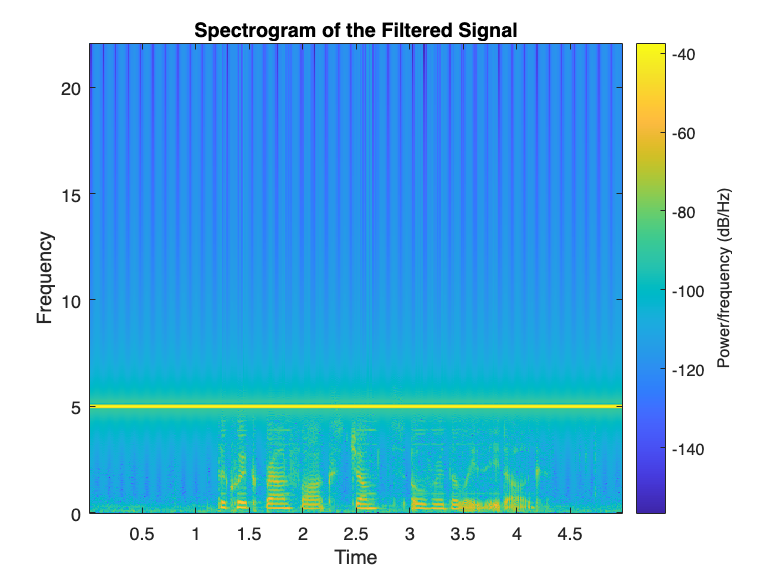

% Load combined audio file
[combined_audio, Fs] = audioread('Carrion-speechchirp.wav');

% Lowpass filter with cutoff frequency of 4000 Hz
cutoff_frequency = 4000;
filter_order = 8;
[b, a] = butter(filter_order, cutoff_frequency/(Fs/2), 'low');

% Apply the filter
filtered_audio = filter(b, a, combined_audio);

% Play the filtered signal
sound(filtered_audio, Fs);

% Save to WAV file
filename = 'Carrion-filteredspeechsine.wav';
audiowrite(filename, filtered_audio, Fs);

% Plot the spectrogram
figure;
spectrogram(filtered_audio, 1024, 512, [], Fs, 'yaxis');
title('Spectrogram of the Filtered Signal');
xlabel('Time');
ylabel('Frequency');

% Save spectrogram
saveas(gcf, 'filtered_speech_spectrogram.png');